
Single objective optimization:
2 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationgaussian

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           5050      -1.43229            0      0
    2          10000      -1.44899            0      0    3          14950      -1.44899            0      1
    4          19900      -1.44899            0      2    5          27510      -1.45038            0      0
Optimization finished: average change in the fitness value less than options.FunctionTolerance and constraint violation is less than options.ConstraintTolerance.


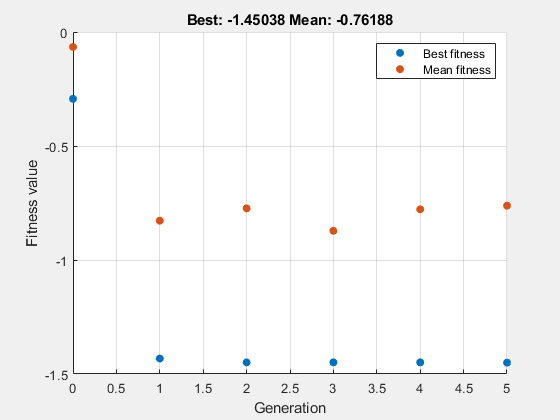

objectiveFcn = @(x) -exp(-x(1)^2 - x(2)^2) - sin(x(1) + x(2));

nonlincon = @(x) deal(...
    [], ...
    []);

options = optimoptions('ga', ...
    'Display', 'iter', ...
    'PlotFcn', @gaplotbestf, ...
    MaxGenerations=200, ...
    PopulationSize=100);

[x_opt, fval] = ga(objectiveFcn, 2, [], [], [], [], [], [], nonlincon, options);

disp('Оптимальное решение:');

Оптимальное решение:


disp(x_opt);

    0.4473    0.4688



disp('Минимальное значение целевой функции:');

Минимальное значение целевой функции:


disp(fval);

   -1.4504



## поверхность

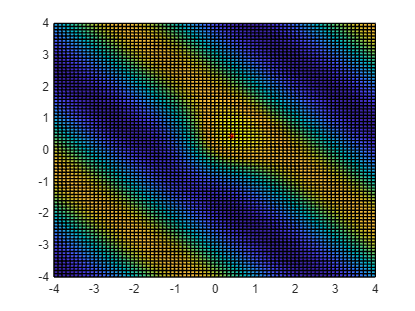

figure
[x, y] = meshgrid(-4:0.1:4, -4:0.1:4);
f = exp(-x.^2 - y.^2) + sin(x + y);
hold on
surface(x, y, f);
plot3(x_opt(1),x_opt(2),-fval,'*r')
grid on;